# Transformacja odwrotna – perfekcyjna rekonstrukcja

to get results run exc01

clear all

S = A.';

if eye(N) == S*A
    disp("SA==I")
else
    disp("SA!=I")
end

SA!=I



% random values matrix 20x20 
rand_matrix = zeros(N,N,100);
X_matrix = zeros(N,N,100);
xs_matrix = zeros(N,N,100);
similarity_matrix = zeros(1,100);
for i=1:100
    rand_matrix(:,:,i) = randn(N);
    X_matrix(:,:,i) = A*rand_matrix(:,:,i);
    xs_matrix(:,:,i) = S*X_matrix(:,:,i);
    similarity_matrix(i) = norm(rand_matrix(:,:,i)-xs_matrix(:,:,i));
end

similarity_matrix

similarity_matrix =     3.3140    4.0998    4.8605    3.8601    4.1877    3.4291    3.8095    3.9309    5.2841    4.1973    3.0793    4.4113    3.1609    4.4166    4.4928    4.9403    3.4293    4.0439    4.3872    4.0925    4.5096    3.7410    3.5067    4.0352    4.0232    4.0980    3.5991    4.0089    3.9741    3.9839    3.6555    3.2825    4.3898    5.0411    4.5600    3.4970    2.6736    3.4340    4.4684    4.2930    4.0551    4.1761    3.1489    4.3018    3.7813    3.8027    3.5273    3.7407    3.9819    3.9386


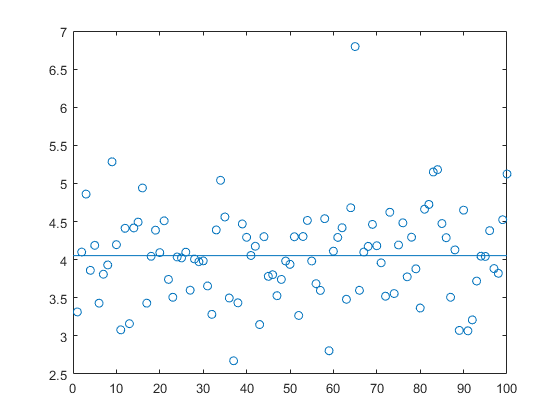


clf
figure
plot(similarity_matrix, 'o')
hold on 
hline = refline([0 mean(similarity_matrix)]);